tsamp = 9.0703e-05

slope = -833.3333

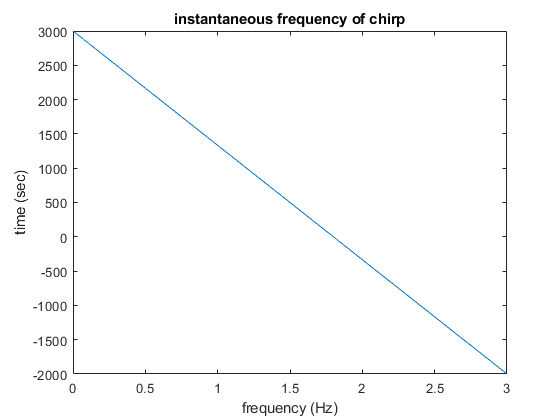

%frequency modulation and amplitude modulation

% f = 4000; %frequency of given sinusoids equal to 4000 Hz
% 
% T = 2.5e-4; %the period of the given sinusoid equal to 1/f
% 
% tt = -T: 0.00001 :T; % a time vector whose range exhibits two cycles of the 4000 Hz sinusoid and passes through 0.
% 
% A1 = 100; %amplitude 1
% A2 = 1.2*A1; %amplitude 2
% 
% M = 12;
% D = 30;
% 
% tm1 = (37.2/M)*T; %phase shift 1
% tm2 = -(41.3/D)*T; %phase shift 2
% 
% x1 = A1*cos(2*pi*4000*(tt - tm1)); %given sinusoid 1
% x2 = A2*cos(2*pi*4000*(tt - tm2)); %given sinusoid 2
% x3 = x2 + x1; %third sinusoid
% 
% %plot of 3 sinusoids
% subplot(3, 1, 1), stem(tt, x1); 
% title("x1");
% subplot(3, 1, 2), stem(tt, x2);
% title("x2");
% subplot(3, 1, 3), stem(tt, x3);
% title("x3");

%Section 2
%-------------------------------

% fsamp = 11025 %sampling frequency
% 
% tsamp = 1/fsamp %sampling period
% 
% duration = 1.8 %total duration of the synthesized signal in seconds
% 
% tt = 0 : tsamp : duration; %time vector

%2.4a
% samples = duration / tsamp %number of samples = 19845
% psi = 2*pi*(100 + 200*tt + 500*tt.*tt); %time-varying angle function
% 
% xx = real(7.7*exp(j*psi)); %real part of complex exponential with argument psi

%2.4b
%tn = n * tsamp = n * (1/fsamp) = n*(1/11025) = n*(9.07e-5)
% A = 7.7
% µ = 500
% f_0 = 200
% ϕ = 2*pi*100 = 200*pi

%soundsc(xx, fsamp); %the frequency is increasing -- this is confirmed by the graph of instantaneous frequency versus time

% N = 8;
% downsampled_xx = downsample(xx, N); %downsample
% f = 11025/N; %sampling frequency
% t = 1/f; %sampling period
%play the downsampled audio to determine the Nyquist rate/aliasing effects
% soundsc(downsampled_xx, fsamp/N)

%Section 3
%-------------------------------

% [xx,tt] = mychirp(2500, 500, 1.5, 11025)
% fsamp = 11025
% soundsc(xx, fsamp)

% fs=8000; xx = cos(3000*pi*(0:1/fs:0.5)); specgram(xx,1024,fs); colorbar

%Section 4
%-------------------------------
% [xx, tt] = beat(10, 10, 1000, 10, 11025, 1);

%plot segment of beat
% xx_segment = xx(1:length(xx)/5);
% tt_segment = tt(1:length(xx)/5);
% plot(tt_segment, xx_segment)
% hold on

%plot envelope of beat
% y = hilbert(xx_segment);
% env = abs(y);
% plot_param = {'Color', [0.6 0.1 0.2],'Linewidth',2}; 
% plot(tt_segment,[-1;1]*env,plot_param{:})
% hold off
% title("beat and hilbert envelope")
% xlabel("time (sec)")
% ylabel("amplitude")

% [xx, tt] = beat(10, 10, 2000, 32, 11025, .26);
% plot(tt, xx)
% title("beat")
% xlabel("time (sec)")
% ylabel("amplitude")
% specgram(xx,2048,fsamp); colormap(1-gray(256))
% specgram(xx,16,fsamp); colormap(1-gray(256))

[xx,tt] = mychirp(3000, -2000, 3, 11025);

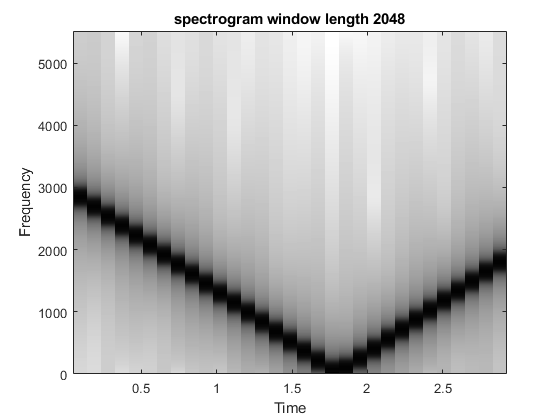

fsamp = 11025;
soundsc(xx, fsamp)
specgram(xx,2048,fsamp); colormap(1-gray(256))
title("spectrogram window length 2048")


% function [xx, tt] = beat(A, B, fc, delf, fsamp, duration)
% tsamp = 1/fsamp; %sampling period
% tt = 0 : tsamp : duration; %time vector
% 
% x1 = A*cos(2*pi*(fc - delf)*tt);
% x2 = B*cos(2*pi*(fc + delf)*tt);
% xx = x1 + x2;

% fb = abs((fc - delf) - (fc + delf));
% beatperiod = 1/fb;
% avgfrequency = abs((fc - delf) + (fc + delf))/2;
% highfreqperiod = 1/avgfrequency;
% disp("beat frequency = |f2 - f1| = " + fb + " Hz")
% disp("beat period = " + beatperiod + " seconds")
% disp("average frequency = |f2 + f1| / 2 = " + avgfrequency + " Hz")
% disp("period of the high frequency underneath the envelope = " + highfreqperiod + " seconds")
%BEAT compute samples of the sum of two cosine waves
% usage:
% [xx, tt] = beat(A, B, fc, delf, fsamp, dur)
%
% A = amplitude of lower frequency cosine
% B = amplitude of higher frequency cosine
% fc = center frequency
% delf = frequency difference
% fsamp = sampling rate
% dur = total time duration in seconds
% xx = output vector of samples
%--Second Output:
% tt = time vector corresponding to xx
%end


function [xx,tt] = mychirp( startingfrequency, endingfrequency, duration, fsamp )
tsamp = 1/fsamp %sampling period

tt = 0 : tsamp : duration; %time vector

slope = (((endingfrequency - startingfrequency) / duration) / 2) %slope of instantaneous frequency

psi = 2*pi*(startingfrequency*tt + slope*tt.*tt); %time-varying angle function

xx = real(exp(j*psi)); %real part of complex exponential with argument psi

%returns sinusoid/complex exponential xx and time vector tt

%plot instantaneous frequency vs time
plot(tt, 2*slope*tt + startingfrequency)
title("instantaneous frequency of chirp")
xlabel("frequency (Hz)")
ylabel("time (sec)")
end